# **Behavior Models **

**In this chapter, you will learn:**

- **What a behavior model is.**

- **Why behavior models are used.**

- **Which types of behavior model exsist within MATLAB.**

When designing complex system, you need to add model equations to your components to test specific scenarios for your models. Model equations use differential, difference and algebraic equations to describe the dynamic behavior of a system. 

To create these models equations, you start with basic principles and data collected from the system. Simulink helps you represent these equations visually in an executable format, allowing you to simulate, observe and modify the system's behavior over time.

Part of this process involves creating algorithms and adding equations to change the model's behavior. For example, you might add a controller algorithm to a motor model to regulatr its speed or filter algorithm to a communication model to remove noise. This allows you to simulate real-life scenarios for your system, such as adding external factors or testing the system with different I/Os to evaulate its stability.

MATLAB provides loads of subsystems, functions and models that help with create model behavior for your system:

- **Conditionally** **Executed** **subsystems** **and** **models**: A conditionally subsystem is a non-virtual subsystem that allows you to control its execution with an external signal. The signal is called a "control signal", and is connected to the input or the control input port. You can think of a conditional subsytem like an if-statement, where the subsystem performs an action when a specific signal or input is detected. There are multiple versions of a [conditional subsystems](https://nl.mathworks.com/help/simulink/conditional-subsystems-1.html) like an action subsytem, or a triggered subsystem.

                                                                                                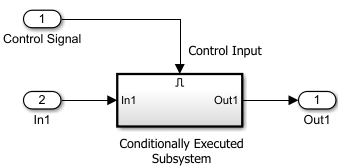

- **Iterator** **subsystems**: An iterator subsystem runs one or more times at the current time step when enabled by a control block. A control block implements control logic similar to that expressed by programming language loop constructs such as while or for. 

                                                                                           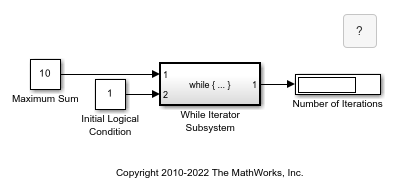

- **Simulink functions**: A Simulink function is a programmatic unit that calculates a set of outputs when provided with a set of inputs. Since a Simulink function provides a common text interface to its function definition and a function caller, how you define the function is your choice.You can create your own Simulink functions by making:

- Simulink blocks in a Simulink Function block.

- Stateflow state transitions in an exported Stateflow graphical function. It is strongly recommended to complete the Stateflow Onramp Course as stateflows can play a significant role Model-Based System Engineering. For the Onramp Course, visit the following link: [Stateflow Onramp Course](https://matlabacademy.mathworks.com/details/stateflow-onramp/stateflow).

- MATLAB code statemements in an exported Stateflow MATLAB function. 

            After you define a function, you can call it using a Function Caller block, a MATLAB function block, or a Stateflow chart.

                                                                                    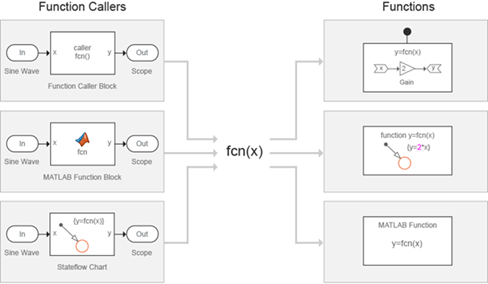

- **Time-based Scheduling models**: Time-Based scheduling is needed for models that rely on a regular time source, like a hardware timer. This means the model follows a set schedule. On the other hand, event-based scheduling is required for systems that must respond to specific event, which can happen at any time and are not aligned with the regular timing source.

                                                                                        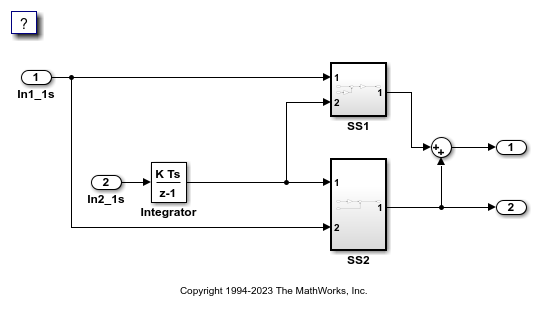

- **Event functions: **Event are notices broadcast when some change or action occurs involving an object. Listeners define functions that execute when specifc event occur. Classes cna define and trigger events. MATLAB can trigger predefined events when code accesses object properties. For example, to make the startup and shutdown behavior of your model more dynamic, you can add custom methods. During the simulation, use events to control when these custom methods/routines execute. Events can trigger these methods at specific times or conditions.

                                                                                                            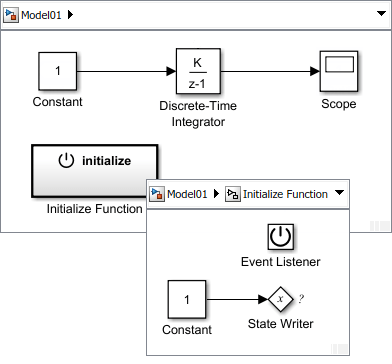

- **Partition Components**: Partitions are components of a model that execute independently as atomic tasks. In multitasking models, partitions are created from model components. With partitions, you can separate parts of the model that you can control in the Schedule Editor Tool. The Schedule Editor Tool is a scheduling tool that represents the components in the model known as parititions, the data connection between them, and the ordering of those partitions. The Schedule Editor can only be used on existing components. The Schedule Editor is an interactive tool that provides an easy way to view and edit the schedule of the model components. 

                                            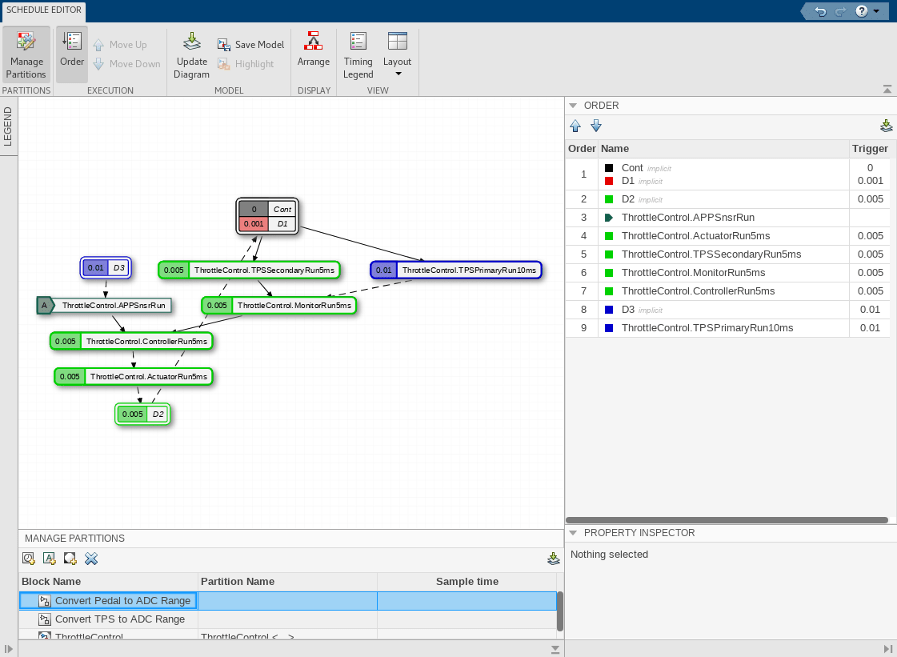

- **Messages**: Messages are used to model communication between Simulink components. You can use messages to establish communication in a complex model whose components perform a defined set of functionalities based on I/O boundaries. Message-based communication between software components is necessary in control system architectures due to system complexity. A message is a useful modeling artifact that combines events with related data. Messages blocks are used to manage the production, consumption, and storage of messages. 

                                                                                                    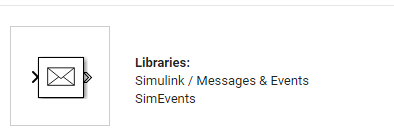

Here's a brief overview of the common behavior models used in complex systems. While thet might seem overwhelming at first, the goal is not to memorize them, but to familiarize yourself with them. For more detailed information about these (and more) behavior models, and how to configure and use them, visit the following link: [Design Model Behavior](https://nl.mathworks.com/help/simulink/design-models.html).

***Test your knowledge:***

""
correctAnswer1 = "external";
correctAnswer2 = "control";
correctAnswer3 = "External";
correctAnswer4 = "Control";
correctAnswer5 = "EXTERNAL";
correctAnswer6 = "CONTROL";

% Check if the user's input matches the correct answer
if strcmpi(ans, correctAnswer1) || strcmpi(ans, correctAnswer2) || strcmpi(ans, correctAnswer3) ||  strcmpi(ans, correctAnswer4) ||  strcmpi(ans, correctAnswer5) ||  strcmpi(ans, correctAnswer6)  
    disp('Congratulations! Your answer is correct.');
else
    disp('Sorry, your answer is incorrect. Try again!');
end

""
correctAnswer1 = "Messages";
correctAnswer2 = "Message";
correctAnswer3 = "messages";
correctAnswer4 = "message";
correctAnswer5 = "MESSAGES";
correctAnswer6 = "MESSAGE";

% Check if the user's input matches the correct answer
if strcmpi(ans, correctAnswer1) || strcmpi(ans, correctAnswer2) || strcmpi(ans, correctAnswer3) ||  strcmpi(ans, correctAnswer4) ||  strcmpi(ans, correctAnswer5) ||  strcmpi(ans, correctAnswer6)  
    disp('Congratulations! Your answer is correct.');
else
    disp('Sorry, your answer is incorrect. Try again!');
end

""
correctAnswer1 = "Schedule Editor Tool";
correctAnswer2 = "Schedule editor tool";
correctAnswer3 = "schedule editor tool";
correctAnswer4 = "SCHEDULE EDITOR TOOL";
correctAnswer5 = "Schedule Editor tool";
correctAnswer6 = "Shedule_Editor_Tool";

% Check if the user's input matches the correct answer
if strcmpi(ans, correctAnswer1) || strcmpi(ans, correctAnswer2) || strcmpi(ans, correctAnswer3) ||  strcmpi(ans, correctAnswer4) ||  strcmpi(ans, correctAnswer5) ||  strcmpi(ans, correctAnswer6)  
    disp('Congratulations! Your answer is correct.');
else
    disp('Sorry, your answer is incorrect. Try again!');
end

""
correctAnswer1 = "Stateflow";
correctAnswer2 = "STATEFLOW";
correctAnswer3 = "stateflow";


% Check if the user's input matches the correct answer
if strcmpi(ans, correctAnswer1) || strcmpi(ans, correctAnswer2) || strcmpi(ans, correctAnswer3) ||  strcmpi(ans, correctAnswer4) ||  strcmpi(ans, correctAnswer5) ||  strcmpi(ans, correctAnswer6)  
    disp('Congratulations! Your answer is correct.');
else
    disp('Sorry, your answer is incorrect. Try again!');
end

 
open("./Chapters/Behavior_Models_Example(14).mlx")